#   Model Evalution

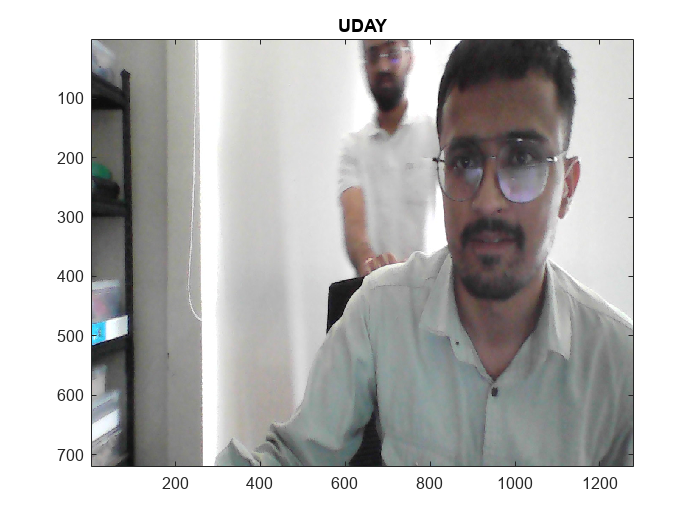

clc
close all


cam = webcam;
load net.mat; % Loading trained network

faceDetector=vision.CascadeObjectDetector;

while true
    e=cam.snapshot;
    bboxes =step(faceDetector,e);
    if(sum(sum(bboxes))~=0)
     es=imcrop(e,bboxes(1,:));
    es=imresize(es,[227 227]);
    label=classify(net,es);
    image(e);
    title(char(label));
    
    drawnow;
    else
        image(e);
        title('No Face Detected');
    end
end